clear;
close all;

## Setup

% Values that we're giving you
Fs = 4e6; % Sampling rate (samples/sec)
Rs = 50e3; % Symbol rate in symbols/sec (baud)
Tmax = 0.1; % Max time for the simulation (sec)
fc = 1e6; % Carrier frequency (Hz)
B = 350e3; % Bandwidth (Hz)

% Complete these expressions using the variables above
N = Fs*Tmax; % Total number of sample points in the simulation
Ns = Rs*Tmax; % Number of symbols to send
sps = Fs/Rs; % Number of samples per symbol

% Use these variables for plotting
t = linspace(0, Tmax-1/Fs, N); % Time vector
f = linspace(-Fs/2, Fs/2, N); % Frequency vector. Recall from 113 that DFT gives us -f/2 to +f/2

## Symbol Generation

Generate random set of bits of 0s and 1s

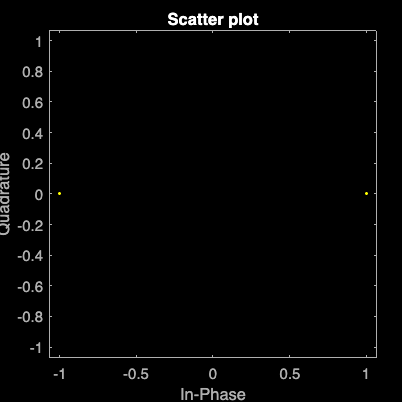

bits = randi([0, 1], 1, Ns);

% Map bits to BPSK symbols of -1s and 1s
symbs = 2 * (bits - 0.5);

% Plot BPSK constellation digram
scatterplot(symbs);

## Carrier Modulation

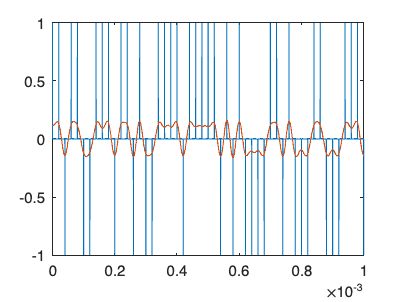

delta_train_symbs = upsample(symbs, sps);
figure
plot(t, delta_train_symbs);
xlim([0 0.001]);

rect_impulse = ones([1, sps]);
rect_filt = conv(delta_train_symbs, rect_impulse, "same"); % conv is a linear operation, the delta train is simply a sum of deltas, distributes out

roll_off = 0.5;
span = 10; % number of symbols to truncate RRC
rrc_impulse = rcosdesign(roll_off, span, sps, "sqrt"); % the number of symbols the impulse response of the RRC impulse response will last for
rrc_filt = conv(delta_train_symbs, rrc_impulse, "same"); %  span: the number of symbols the impulse response of the RRC impulse response will last for

% The total length of the impulse response is then sps*span.

hold on
plot(t, rrc_filt);


% Modulation
phase = unifrnd(0, 2*pi);
disp(["Phase: ", phase]);

    "Phase: "    "1.0611"



carrier = exp(-1i*(fc*t+phase));
analytic_signal = carrier .* rrc_filt;
analytic_signal = real(analytic_signal);


## Channel

channel_filter = "NONE";

if (channel_filter == "NONE") 

elseif (channel_filter == "Tustin")
    s = tf('s');
    Hc = B*s/(s^2 + s*B + fc^2);
    Hd = c2d(Hc, 1/Fs, 'tustin');
    [a, b] = tfdata(Hd);
    analytic_signal = real(filter(a{:}, b{:}, analytic_signal));
else

end

## Carrier Demodulation

Costas Loop

wc = 2*pi*fc;

rec_in_phase = zeros(1, numel(analytic_signal));
rec_quad = zeros(1, numel(analytic_signal));
error = zeros(1, numel(analytic_signal));

Kp = 0.1;
Ki = 0.001;
integrator = 0;

lp = firpm(5, [0,0.2,0.4,1], [1,1,0,0]);
lp_length = length(lp);

for idx =1:numel(analytic_signal)
    
    rec_in_phase(idx) = analytic_signal(idx) * 2*cos( * idx + new_phase);
    rec_quad(idx) = analytic_signal(idx) * -2*sin( * idx + new_phase);                          

    filt_in_phase = filter(lp, 1, rec_in_phase(prev_idx:idx));
    filt_quad = filter(lp, 1, rec_quad(prev_idx:idx));
    
    error(idx) = filt_in_phase(end) * filt_quad(end);
    integrator = integrator + error(idx);
    new_phase = old_phase + Kp*error(idx) + Ki*integrator;

    old_phase = new_phase;

%     x = A' \ phase'; % matrix division -- that's a way of getting the slope?
%     slope = x(1);
%     if (abs(slope - phase(idx)/Fs) > 1e-5); disp("BAD"); end 

end

% p(t) conv with rrc
rec_in_phase = -conv(rec_in_phase, rrc_impulse, "same");

hold on 
plot(t, rec_in_phase);

legend('Symbol Delta Train', 'Transmitted Baseband', 'Received Baseband');

% 1/10 symbol rate
% filter out the carrier signal
f_cutoff = 5000; % not cut-off frequency should be somewhere between the bandwidth of the modulation and double the carrier frequency.

## Symbol Detection

rec_samples = rec_in_phase(1:sps:N);
rec_bits = zeros([1, Ns]);
for i=1:Ns
    if (rec_samples(i) > 0); rec_bits(i) = 1; else; rec_bits(i) = 0; end
end

scatterplot(rec_samples);


total_err_plt = zeros(1, Ns);
total_err = 0;
for idx=1:Ns
    if (rec_bits(idx) ~= bits(idx))
        total_err = total_err + 1;
    end
    total_err_plt(idx) = total_err;
end
figure();
plot(1:Ns, total_err_plt);


% err_rate = sum(rec_bits ~= bits) / Ns;